# MATLAB & Mobile Phone Sensors

Using "MATLAB Mobile" to access organic cell phone sensors and to export data file to "MATLAB Drive." 

Experiment A: Turn on the acceleration sensor. Place the cell phone flat on the table. Collect data for 1-2 minutes. Download the data file from MATLAB Drive.

Load acceleration data file to workspace

load("C:\Users\m260477\Desktop\EW202\ICE\ICE2\Z_Acceleration.mat")
Acceleration

Acceleration = 613×3 timetable
           Timestamp                X           Y          Z   
    ________________________    _________    ________    ______

    22-Jan-2024 10:01:28.978    -0.032183     0.13652    9.8432
    22-Jan-2024 10:01:29.078     0.058079     0.14175     9.848
    22-Jan-2024 10:01:29.178     0.036225     0.12065    9.8601
    22-Jan-2024 10:01:29.279      -0.0479    0.097896    9.8551
    22-Jan-2024 10:01:29.379      0.10134     0.16421     9.856
    22-Jan-2024 10:01:29.479    -0.037722     0.12664    9.8613
    22-Jan-2024 10:01:29.579     0.085772     0.13966    9.8314
    22-Jan-2024 10:01:29.680    -0.027543     0.10059    9.8607
    22-Jan-2024 10:01:29.780     0.0498

Plot vertical acceleration data (Z axis data when the cell phone is placed face-up on table)

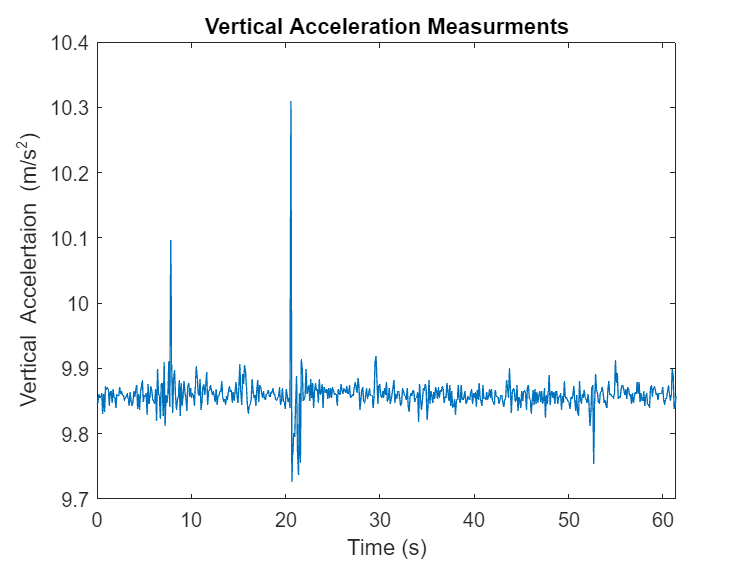

time = Acceleration.Timestamp;
% Calculate the difference between timestamps and cumulative sum them 
x = seconds(cumsum(diff(time))); 
x = [0; x]; % Time starts at 0 seconds
z = Acceleration.Z;
plot(x,z)
title("Vertical Acceleration Measurments")
xlabel("Time (s)")
ylabel("Vertical Accelertaion (m/s^2)")
xlim("tight")

Find the latest value of the vertical acceleration

z(end)

ans = 9.8582

Is this value a good estimate of the steady state?

Not really... Its just the last value. Doesn't represent the whole sample data collected.

Find a better estimate of the steady-state value

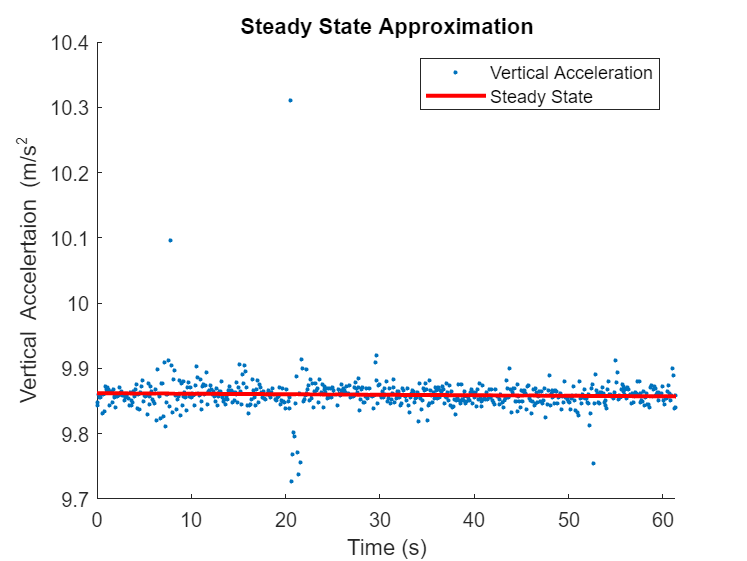

scatter(x,z,".")
pfit = polyfit(x,z,1);
pval = polyval(pfit,x);
hold on
plot(x,pval,"r","LineWidth",2)
title("Steady State Approximation")
legend(["Vertical Acceleration" "Steady State"])
xlabel("Time (s)")
ylabel("Vertical Accelertaion (m/s^2")
xlim("tight"),
hold off

trimmed_mean_estimate = trimmean(z,10)

trimmed_mean_estimate = 9.8591

What is the value of the acceleration of gravity?

9.81

Write a logical IF statement to declare (or not) error in the measurement of g=9.81 m/s^2:

if trimmed_mean_estimate ~= 9.81
    disp('There is measurement error')
else
    disp('There is no measurement error')
end

There is measurement error


How is acceleration measured in general? What type of accelerometer is inside the cell phone?

Accleration is the change in velocity with resepect to time. 

MEMS-based accelerometer.

[STRETCH] Experiment B: Generate orientation data (e.g., change the pitch anlge, that is, the angle from the table to the plane of the phone). Load orientation data file to workspace

load("C:\Users\m260477\Desktop\EW202\ICE\ICE2\Y_Acceleration.mat")
Acceleration

Acceleration = 230×3 timetable
           Timestamp                X           Y          Z   
    ________________________    _________    ________    ______

    22-Jan-2024 14:21:04.701     0.012274      0.0479     9.872
    22-Jan-2024 14:21:04.801      0.00015    0.016915     9.851
    22-Jan-2024 14:21:04.901    -0.030986    0.006137    9.8467
    22-Jan-2024 14:21:05.002    -0.044907    0.034279    9.8581
    22-Jan-2024 14:21:05.102    -0.024699    0.062271    9.8769
    22-Jan-2024 14:21:05.202    -0.005688    0.055684    9.8552
    22-Jan-2024 14:21:05.302     0.054487    0.051942    9.9874
    22-Jan-2024 14:21:05.403     -0.00943     0.28531    10.735
    22-Jan-2024 14:21:05.503      0.109

Plot orientation data

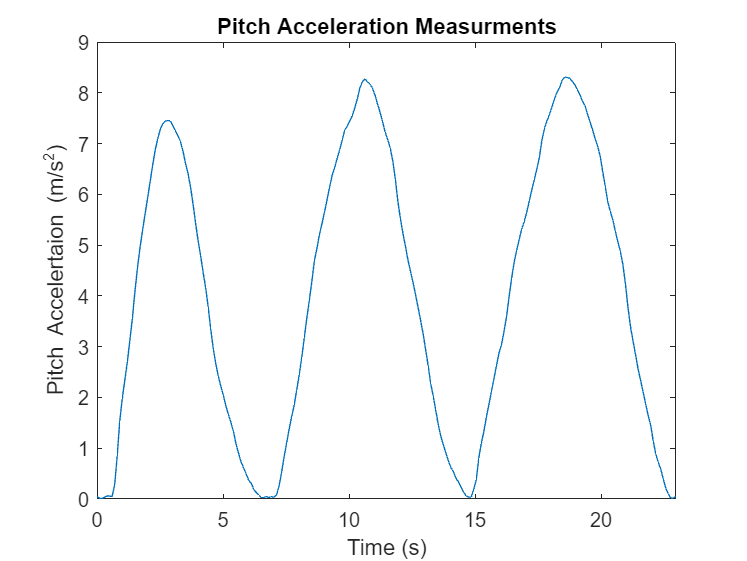

time = Acceleration.Timestamp;
% Calculate the difference between timestamps and cumulative sum them 
x = seconds(cumsum(diff(time))); 
x = [0; x]; % Time starts at 0 seconds
y = Acceleration.Y;
plot(x,y)
title("Pitch Acceleration Measurments")
xlabel("Time (s)")
ylabel("Pitch Accelertaion (m/s^2)")
xlim("tight")

Does the graph capture the pitch angle correctly?

Yes!

*Prof Kiriakos Kiriakidis (Jan 18, 2024).*